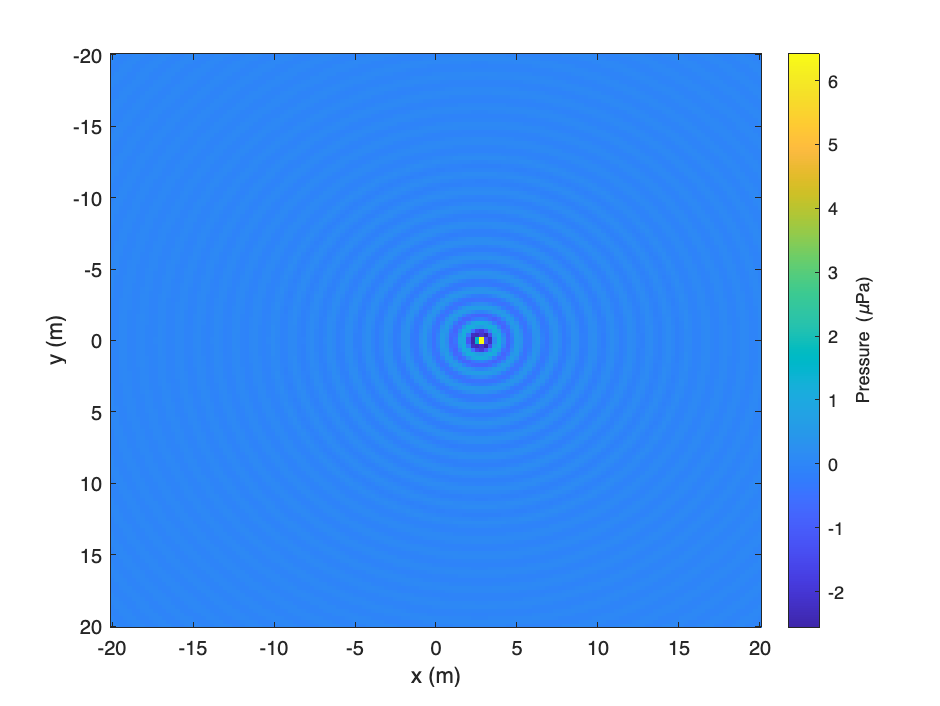

f = 1290; % frequency in Hz
d = 5.5; % Seperation between sources
c = 1500 ; % Speed of sound (m/s)


dmax = 10; % Maximum seperation between sources
Lx = 2*dmax; % Range of calculation
Ly = 2*dmax;
Nx = 150;
Ny = Nx;
x = linspace(-Lx,Lx,Nx);
y = linspace(-Ly,Ly,Ny);

SL = 0; % SL is 0 dB
A_SL = (10^(SL/20)); % pressure amplitude of source (microPascal)

[X,Y] = meshgrid(x,y);

r1 = sqrt((X - d/2).^2 + Y.^2); % distance from source #1 to each point
r2 = sqrt((X + d/2).^2 + Y.^2); % distance from source #2 to each point

SourceState = 0; % Turn source #2 on or off
if SourceState
    A2 = 1;
else
    A2 = 0;
end



p1 = A_SL.*exp(1i*2*pi*f*r1/c)./r1;     % Pressure due to source #1
p2 = A_SL.*A2.*exp(1i*2*pi*f*r2/c)./r2; % Pressure due to source #2
p = p1 + p2; % Coherent sum of pressures

plotType = 0;

if plotType == 0
    imagesc(x,y,real(p)*sqrt(2))
    a = gca;
    a.XLabel.String = 'x (m)';
    a.YLabel.String = 'y (m)';
    c1 = colorbar;
    c1.Label.String = 'Pressure (\muPa)';

else
    imagesc(x,y,20*log10(abs(p)))
    a = gca;
    a.XLabel.String = 'x (m)';
    a.YLabel.String = 'y (m)';
    c1 = colorbar;
    c1.Label.String = 'Intensity (dB re 1\muPa)';
end

Concepts to discuss with this widget:

- Free space propagation

- Constructive interference

- Destructive interference